eng1 = eng_tot;
[error,indx] = max(abs(1-eng1));
w1 = incident.w;
pX = MATERIAL.CT/B/2/pi;
ff1 = w1*pX;

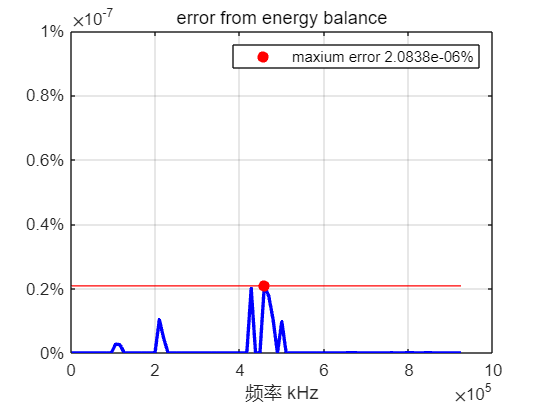

p1 = plot(ff1,abs(1-eng1), ...
	'LineWidth',2, 'Color','b');
hold on
p2 = plot(ff1(indx),error,'r.',MarkerSize=20);
p3 = plot(ff1,error*ones(size(ff1)),'r');
hold off
% xlabel(["dimensionless frequency"; "$$k_d$$"],Interpreter="latex");
xlabel("频率 kHz")	
ytickformat('percentage')
grid on


ylim([0,1e-7])
legendTxt = ['maxium error ', num2str(error*100),'%'];
legend("",legendTxt)
title('error from energy balance')